ch4_yyc_201 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202001_06.mat','ch4')));
cc_yyc_201 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202001_06.mat','coverage_count')));
ch4_yyc_202 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202007_12.mat','ch4')));
cc_yyc_202 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202007_12.mat','coverage_count')));
ch4_yyc_211 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202101_06.mat','ch4')));
cc_yyc_211 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202101_06.mat','coverage_count')));
ch4_yyc_212 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202107_12.mat','ch4')));
cc_yyc_212 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202107_12.mat','coverage_count')));
% ch4_yyc_22 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\yyc_2022.mat','ch4')));
% cc_yyc_22 = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\yyc_2022.mat','coverage_count')));
grid_lat = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202001_06.mat','grid_lat')));
grid_lon = cell2mat(struct2cell(load('D:\Urban_methane\data\processed_data\mat\202001_06.mat','grid_lon')));
load('D:\Urban_methane\data\processed_data\mat\202001_06.mat','maxlat','maxlon','minlat','minlon');

cc_yyc_201(isnan(cc_yyc_201)) = 0;cc_yyc_202(isnan(cc_yyc_202)) = 0;
cc_yyc_211(isnan(cc_yyc_211)) = 0;cc_yyc_212(isnan(cc_yyc_212)) = 0;
% cc_yyc_22(isnan(cc_yyc_22)) = 0;
cc_yyc = cc_yyc_201 + cc_yyc_202 + cc_yyc_212 + cc_yyc_212; %+ cc_yyc_22;
ch4_yyc = ch4_yyc_201;
ch4_yyc(:,:,size(ch4_yyc,3)+1:size(ch4_yyc,3)+size(ch4_yyc_202,3)) = ch4_yyc_202;
ch4_yyc(:,:,size(ch4_yyc,3)+1:size(ch4_yyc,3)+size(ch4_yyc_211,3)) = ch4_yyc_211;
ch4_yyc(:,:,size(ch4_yyc,3)+1:size(ch4_yyc,3)+size(ch4_yyc_212,3)) = ch4_yyc_212;
% ch4_yyc(:,:,size(ch4_yyc,3)+1:size(ch4_yyc,3)+size(ch4_yyc_22,3)) = ch4_yyc_22;

load('D:\Emission_estimate\TROPOMI_CH4\processed_data\mat\Overview\ROI\wc_regions.mat');

[ wlon_20,wlat_20,uwind_mw_20,vwind_mw_20,surface_pressure_mw_20,edge_heights_mw_20 ] = ...
    merra2wind( num2str(2020),'all' );
[ wlon_21,wlat_21,uwind_mw_21,vwind_mw_21,surface_pressure_mw_21,edge_heights_mw_21 ] = ...
    merra2wind( num2str(2021),'all' );
% [ wlon_22,wlat_22,uwind_mw_22,vwind_mw_22,surface_pressure_mw_22,edge_heights_mw_22 ] = ...
%     merra2wind( num2str(2022),'all' );

uwind_mw = ( uwind_mw_21 + uwind_mw_20)/2;
vwind_mw = ( vwind_mw_21 + vwind_mw_20)/2;
surface_pressure_mw = ( surface_pressure_mw_21 + surface_pressure_mw_20)/2;
wlon = wlon_21; wlat = wlat_21;
layers_nrsur = [1:6]; % The near-surface layers for wind data.
uwind = mean(uwind_mw(:,:,layers_nrsur),3,"omitnan"); % The near-surface eastward wind speed.
vwind = mean(vwind_mw(:,:,layers_nrsur),3,"omitnan"); % The near-surface northward wind speed.

load('D:\Urban_methane\data\processed_data\mat\yyc_ws_ams_2020-2021.mat','ws_mean_vc','ws_std_vc');

ch4_yyc_mean = mean(ch4_yyc,3,"omitmissing"); % Annual mean XCH4
ch4_yyc_std = std(ch4_yyc,0,3,"omitnan"); % Annual stdev XCH4
ch4_yyc_mean = imgaussfilt(ch4_yyc_mean,1,'FilterSize',3); % Conduct Gaussian filtering 
cc_yyc(cc_yyc==0) = nan; % replace 0 with nan in the total coverage count matrix
n_min = 10;% Threshold of valid obervation numbers for quantification, e.g. 5, 10, 20，30.
robust_nobs = cc_yyc >= n_min;
cc_yyc = cc_yyc .* robust_nobs;
cc_yyc(cc_yyc == 0) = nan;
ch4_yyc_mean = ch4_yyc_mean .* robust_nobs;
ch4_yyc_mean(ch4_yyc_mean == 0) = nan;
ch4_yyc_std = ch4_yyc_std .* robust_nobs;
ch4_yyc_std(ch4_yyc_std == 0) = nan;

mch4 = ch4_yyc_mean;surface_pressure = surface_pressure_mw;
wind(:,:,1) = uwind;wind(:,:,2) = vwind;
cell_area = 0.05 .* 111.32 .* 0.05 .* 111.32 .* cosd(grid_lat); % the pixel specific area in km^2.
M = 5.345; % M is a constant conversion factor (5.345 × 1e−9 MtCH4/km2/ppb or 5.345 kg/km2/ppb)
C = 2;
emi_mb = struct;
for i = 3:3
    lat = roi_wc(i).Latitude; lon = roi_wc(i).Longitude;
    lat_b = roi_wc(i+6).Latitude; lon_b = roi_wc(i+6).Longitude;
    [in,on] = inpolygon(grid_lon,grid_lat,lon,lat);
    in = in + on;
    in(in>1)=1;
    [in_b,on_b] = inpolygon(grid_lon,grid_lat,lon_b,lat_b);
    in_b = in_b + on_b;
    in_b(in_b>1)=1;
    in_sur = in;
    in_sur(in_sur==0)=2;
    in_sur(in_sur==1)=0;
    in_sur(in_sur==2)=1;
    in_sur = in_sur .* in_b;
    [in_mw,on_mw] = inpolygon(wlon,wlat,lon_b,lat_b);
    in_mw = in_mw + on_mw;
    in_mw(in_mw>1)=1;
    ch4_b = in_b .* mch4; ch4_b(ch4_b == 0) = nan;% data out of the roi filled with nan
    ch4_roi = in .* mch4; ch4_roi(ch4_roi == 0) = nan;% data out of the roi filled with nan
    area_roi = in .* cell_area;area_roi(area_roi == 0) = nan;% data out of the roi filled with nan
    u_roi = in_mw .* wind(:,:,1); u_roi(u_roi == 0) = nan;% data out of the roi filled with nan
    v_roi = in_mw .* wind(:,:,2); v_roi(v_roi == 0) = nan;% data out of the roi filled with nan
    ws_roi = sqrt(u_roi.^2 +v_roi.^2); % array of wind speed over roi.
    % mean_ws = mean(ws_roi,"all","omitnan"); % the mean wind speed over roi, m/s.
    % std_ws = std(ws_roi,0,"all","omitnan"); % the mean wind speed over roi, m/s.
    mean_ws = ws_mean_vc; % the observed mean wind speed over roi, m/s.
    std_ws = ws_std_vc; % the stdev of theobserved wind speed over roi, m/s.
    surfp_roi = in_mw .* surface_pressure; surfp_roi(surfp_roi == 0) = nan;% data out of the roi filled with nan
    mean_b = mean(ch4_b(:),'omitnan');
    median_b = median(ch4_b(:),'omitnan');
    std_b = std(ch4_b(:),'omitnan');
    c = (mean_b-median_b)/std_b;
    if c>0.3
        bgd_b = median_b;
    else
        bgd_b = (2.5 * median_b) - (1.5 * mean_b);
    end
    mean_roi = mean(ch4_roi(:),'omitnan');
    std_roi = std(ch4_roi(:),'omitnan');
    delta_roi = ch4_roi - bgd_b; % the enhancement of XCH4 over roi
    delta_roi(delta_roi < 1*std_roi) = nan; % Exclude the enhancement smaller than the standard deviation.
    N = sum(~isnan(delta_roi(:))); % Obtain the number of source cells.
    d_roi(:,:,i) = delta_roi;
    std_delta_roi = std(delta_roi(:),'omitnan');
    mean_delta_roi = mean(delta_roi(:),'omitnan'); % the mean enhancement of XCH4 over roi
    M_exp = mean(surfp_roi(:),'omitnan') ./ (100*1013.0);
    L = sqrt(N*(0.05*111.32 * 0.05 * cos(mean(lat(:),'omitnan').*pi/180) * 111.32)); % the effective size of the emission region
    V = mean_ws * 60 * 60 * 24 / 1000; % convert the m/s to km/d
    V_unc = std_ws * 60 * 60 * 24 / 1000; % convert the m/s to km/d
    %% The equation to calculate the emissions
    est_emi_mb = mean_delta_roi .* M .* M_exp .* L .* V .* C ./ 1000; % the unit of emission is t/d
    %% The following equations to calculate the uncertainties
    est_unc_delta = std_delta_roi .* M .* M_exp .* L .* V .* C ./ 1000; % the unit is t/d
    est_unc_wind = mean_delta_roi .* M .* M_exp .* L .* V_unc .* C ./ 1000; % the unit is t/d
    est_unc_total = sqrt(est_unc_delta.^2+est_unc_wind.^2); % the unit is t/d
    %% Save the parameters and emissions
    emi_mb(i).mean_xch4_b = mean_b;
    emi_mb(i).stdev_xch4_b = std_b;
    emi_mb(i).median_xch4_b = median_b;
    emi_mb(i).background_xch4 = bgd_b;
    emi_mb(i).mean_xch4_roi = mean_roi;
    emi_mb(i).stdev_xch4_roi = std_roi;
    emi_mb(i).enhancement_xch4 = mean_delta_roi;
    emi_mb(i).number_of_source_cells = N;
    emi_mb(i).area_roi = sum(area_roi(:),"all","omitnan");
    emi_mb(i).dimensionless_factor = M_exp;
    emi_mb(i).wind_speed = mean_ws;
    emi_mb(i).wind_std = std_ws;
    emi_mb(i).estimated_emission = est_emi_mb;
    emi_mb(i).estimated_uncertainty_delta = est_unc_delta;
    emi_mb(i).estimated_uncertainty_wind = est_unc_wind;
    emi_mb(i).estimated_uncertainty_total = est_unc_total;
    emi_mb(i).region = roi_wc(i).Region;
    emi_mb(i).estimated_flux = est_emi_mb*365/sum(area_roi(:),"all","omitnan"); % emission flux, t/yr/km2
    emi_mb(i).flux_uncertainty_delta = est_unc_delta*365/sum(area_roi(:),"all","omitnan");
    emi_mb(i).flux_uncertainty_wind = est_unc_wind*365/sum(area_roi(:),"all","omitnan");
    emi_mb(i).flux_uncertainty_total = est_unc_total*365/sum(area_roi(:),"all","omitnan");
end

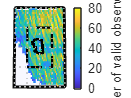

land = shaperead('landareas', 'UseGeoCoords', true); % Coastal lines
lakes = shaperead('worldlakes', 'UseGeoCoords', true); % Lakes
states=shaperead("usastatelo.shp",'UseGeoCoords',true);
figure;
ax = worldmap([minlat maxlat],[minlon maxlon]);
geoshow(ax, land, 'FaceColor', [248/255 248/255 255/255]);
hold on
geoshow(ax, [countries(:).Y], [countries(:).X],...
    'DisplayType',"polygon", 'FaceAlpha',0,...
    "LineWidth",1.25,"FaceColor",[0 1 1]);
geoshow(ax, lakes, 'FaceColor','white');
geoshow(states, 'DisplayType',"polygon","FaceAlpha",0,"LineWidth",1);
surfm(grid_lat,grid_lon,cc_yyc); % Create a pixel-specific XCH4 map.
clim([0 80]);
cb = colorbar;
cb.XLabel.String = 'Number of valid observations';
plotm(roi_wc(3).Latitude,roi_wc(3).Longitude,'k','linewidth',1.25); % Display the ROIs
plotm(roi_wc(9).Latitude,roi_wc(9).Longitude,'k--','linewidth',1.25); % Display the ROIs

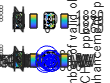

land = shaperead('landareas', 'UseGeoCoords', true); % Coastal lines
lakes = shaperead('worldlakes', 'UseGeoCoords', true); % Lakes
states=shaperead("usastatelo.shp",'UseGeoCoords',true);
facilities_yyc = readtable('D:\Urban_methane\data\processed_data\xls\ghgrp_2020_2021.xlsx',...
    'Sheet','ghgrp_2020_2021','Range','I2:M83','ReadVariableNames',false); % Read the reported facilities in GHGRP.
facilities_yyc = table2array(facilities_yyc);
figure;
% subplot(2,3,1)
ax = worldmap([minlat maxlat],[minlon maxlon]);
geoshow(ax, land, 'FaceColor', [248/255 248/255 255/255]);
hold on
geoshow(ax, [countries(:).Y], [countries(:).X],...
    'DisplayType',"polygon", 'FaceAlpha',0,...
    "LineWidth",1.25,"FaceColor",[0 1 1]);
geoshow(ax, lakes, 'FaceColor','white');
geoshow(states, 'DisplayType',"polygon","FaceAlpha",0,"LineWidth",1);
surfm(grid_lat,grid_lon,cc_yyc); % Create a pixel-specific XCH4 map.
clim([0 80]);
cb = colorbar;
cb.XLabel.String = 'Number of valid observations';
plotm(roi_wc(3).Latitude,roi_wc(3).Longitude,'k','linewidth',1.25); % Display the ROIs
plotm(roi_wc(9).Latitude,roi_wc(9).Longitude,'k--','linewidth',1.25); % Display the ROIs
subplot(2,3,2)
ax = worldmap([minlat-0.01 maxlat+0.01],[minlon maxlon]);
geoshow(ax, land, 'FaceColor', [248/255 248/255 255/255]);
hold on
geoshow(ax, [countries(:).Y], [countries(:).X],...
    'DisplayType',"polygon", 'FaceAlpha',0,...
    "LineWidth",1.25,"FaceColor",[0 1 1]);
geoshow(ax, lakes, 'FaceColor','white');
geoshow(states, 'DisplayType',"polygon","FaceAlpha",0,"LineWidth",1);
surfm(grid_lat,grid_lon,ch4_yyc_mean); % Create a pixel-specific XCH4 map.
clim([1860 1883]);
cb = colorbar;
cb.XLabel.String = 'XCH_4, ppb';
plotm(roi_wc(3).Latitude,roi_wc(3).Longitude,'k','linewidth',1.25); % Display the ROIs
plotm(roi_wc(9).Latitude,roi_wc(9).Longitude,'k--','linewidth',1.25); % Display the ROIs
subplot(2,3,4)
ax = worldmap([minlat+0.5 maxlat-0.5],[minlon+0.5 maxlon-0.499]);
geoshow(ax, land, 'FaceColor', [248/255 248/255 255/255]);
hold on
geoshow(ax, [countries(:).Y], [countries(:).X],...
    'DisplayType',"polygon", 'FaceAlpha',0,...
    "LineWidth",1.25,"FaceColor",[0 1 1]);
geoshow(ax, lakes, 'FaceColor','white');
geoshow(states, 'DisplayType',"polygon","FaceAlpha",0,"LineWidth",1);
surfm(grid_lat,grid_lon,ch4_b); % Create a pixel-specific XCH4 map.
clim([1860 1883]);
cb = colorbar;
cb.XLabel.String = 'XCH_4, ppb';
plotm(roi_wc(3).Latitude,roi_wc(3).Longitude,'k','linewidth',1.25); % Display the ROIs
plotm(roi_wc(9).Latitude,roi_wc(9).Longitude,'k--','linewidth',1.25); % Display the ROIs
subplot(2,3,5)
% ax = worldmap([minlat+0.5 maxlat-0.5],[minlon+0.5 maxlon-0.5]);
ax = worldmap([50.8 51.3],[-114.35 -113.8]);
geoshow(ax, land, 'FaceColor', [248/255 248/255 255/255]);
hold on
geoshow(ax, [countries(:).Y], [countries(:).X],...
    'DisplayType',"polygon", 'FaceAlpha',0,...
    "LineWidth",1.25,"FaceColor",[0 1 1]);
geoshow(ax, lakes, 'FaceColor','white');
geoshow(states, 'DisplayType',"polygon","FaceAlpha",0,"LineWidth",1);
d_ch4_roi = ch4_roi-bgd_b;
d_ch4_roi(d_ch4_roi<0) = nan;
surfm(grid_lat,grid_lon,d_ch4_roi); % Create a pixel-specific XCH4 map.
clim([0 8]);
cb = colorbar;
cb.XLabel.String = 'XCH4 enhancement, ppb';
plotm(roi_wc(3).Latitude,roi_wc(3).Longitude,'k','linewidth',1.25); % Display the ROIs
plotm(roi_wc(9).Latitude,roi_wc(9).Longitude,'k--','linewidth',1.25); % Display the ROIs
scatterm(facilities_yyc(:,1),facilities_yyc(:,2),facilities_yyc(:,5)/10+5,'blue','o');
scatterm([50.85,50.88,50.91,50.94],[-114.3,-114.3,-114.3,-114.3],...
    [10/10+5,100/10+5,500/10+5,1000/10+5,],'blue','o');